%Robust control SC42145
%Kinge Keulen (5067162)
%Hannah Gielen ()
addpath('/Users/kingekeulen/Documents/GitHub/Robust-Control-2024');
clear
close

load('Assignment_Data_SC42145.mat')

% Transfer function of the open loop system
G = tf(FWT);

G_11 = -1*G(1,1); % From Beta to Omega x -1
disp(G_11)

  tf with properties:

       Numerator: {[0 0.0799 0.0033 0.8677 -0.0065 0.0346]}
     Denominator: {[1 0.5979 10.9759 4.7093 0.5421 0.1827]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {'Beta (deg)'}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]




disp(stepinfo(G_11));

         RiseTime: 13.6517
    TransientTime: 168.7029
     SettlingTime: 168.7029
      SettlingMin: 0.1704
      SettlingMax: 0.2086
        Overshoot: 10.2142
       Undershoot: 0
             Peak: 0.2086
         PeakTime: 26.4813



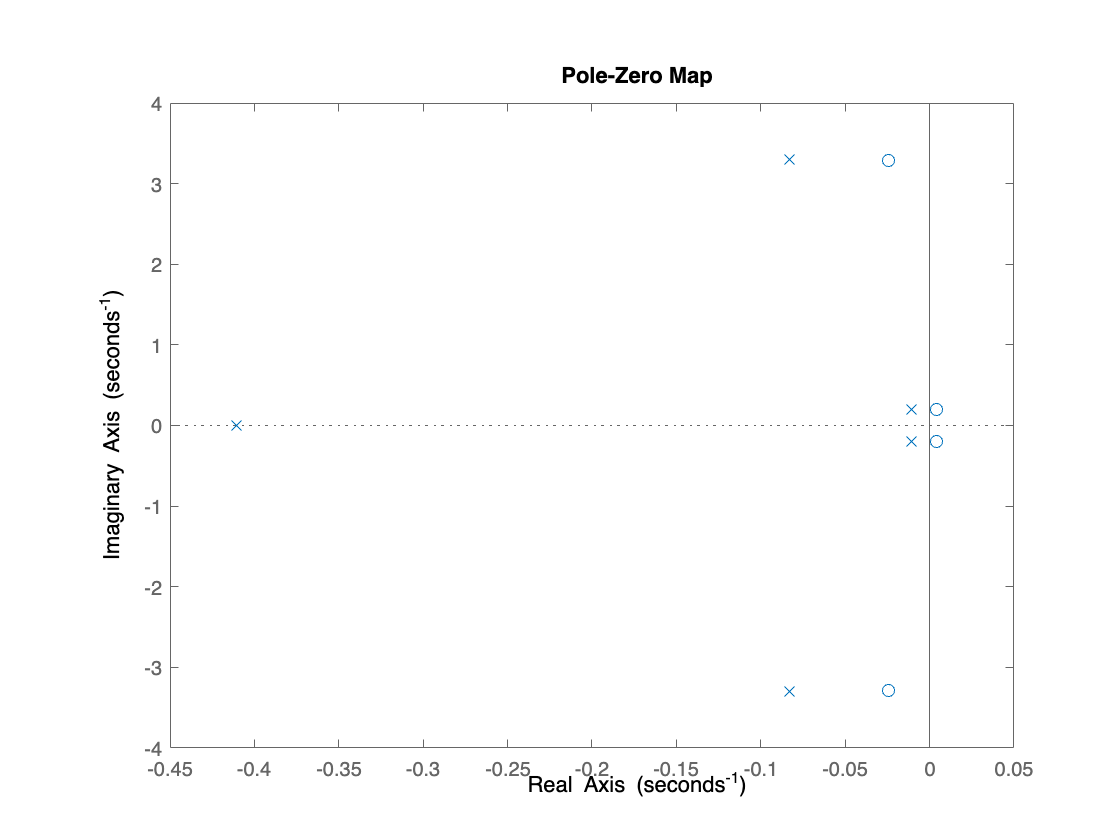

%% Question 1

figure('Name','Figure 1.1','NumberTitle','off')
pzmap(G_11) % pole-zero map of the SISO transfer function

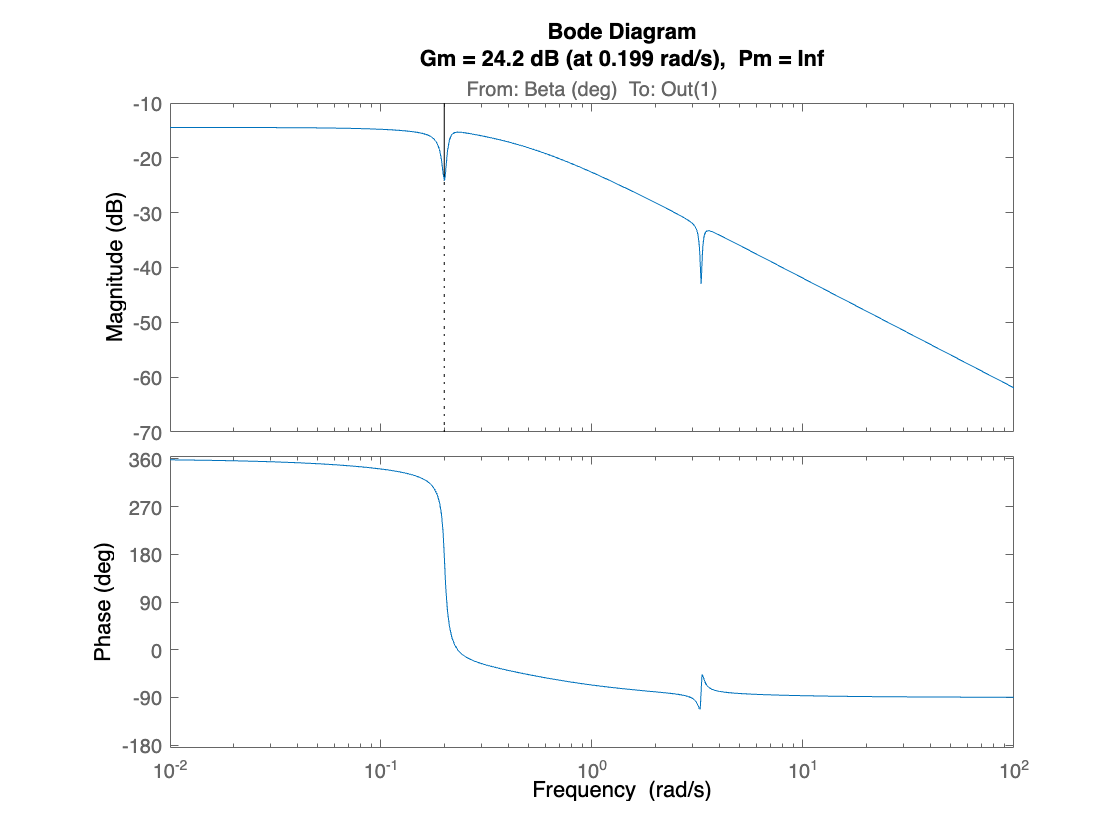


figure('Name','Figure 1.2','NumberTitle','off')
margin(G_11) % bode plot of the SISO transfer function

disp(dcgain(G_11));

    0.1893



disp(bandwidth(G_11));

    0.1851



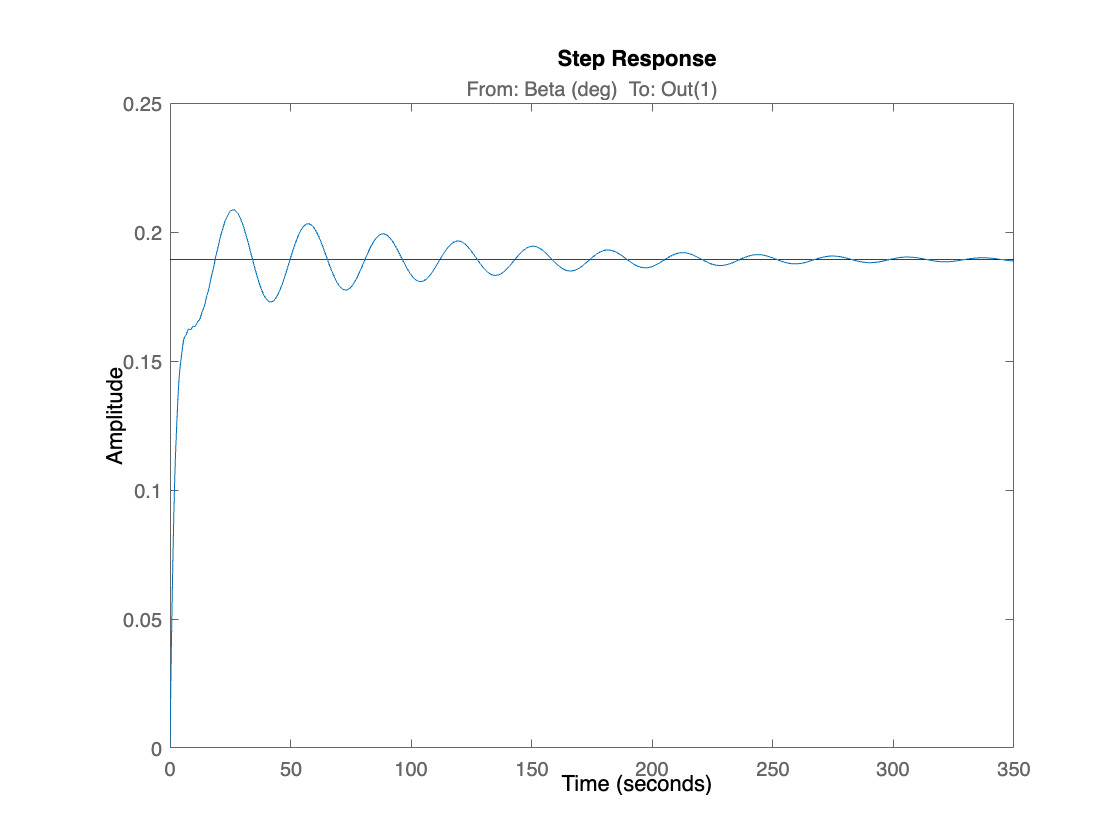


% Plot step response
figure('Name', 'Step response of SISO system');
step(G_11);

## PI-controller


s = tf('s');

Kp = 0.6;
Ki = 0.25;

C_ref = pid(Kp, Ki);

% open loop
L = C_ref * G_11;

% closed loop
T = feedback(L,1);

% Display stepinfo of reference tracking PI controller
disp('Stepinfo of closed-loop SISO system with reference tracking PI controller:')

Stepinfo of closed-loop SISO system with reference tracking PI controller:


disp(stepinfo(T));

         RiseTime: 48.2201
    TransientTime: 84.3987
     SettlingTime: 84.3987
      SettlingMin: 0.9010
      SettlingMax: 1.0072
        Overshoot: 0.7152
       Undershoot: 0
             Peak: 1.0072
         PeakTime: 125.6598




% Display bandwidth of reference tracking PI controller
disp('Bandwidth of closed-loop SISO system with reference tracking PI controller:')

Bandwidth of closed-loop SISO system with reference tracking PI controller:


disp(bandwidth(T));

    0.0490




% Display DC-gain to find possible steady-state error
disp('DC-gain of closed-loop SISO system with reference tracking PI controller, value of 1 indicates no steady-state error:')

DC-gain of closed-loop SISO system with reference tracking PI controller, value of 1 indicates no steady-state error:


disp(dcgain(T));

     1



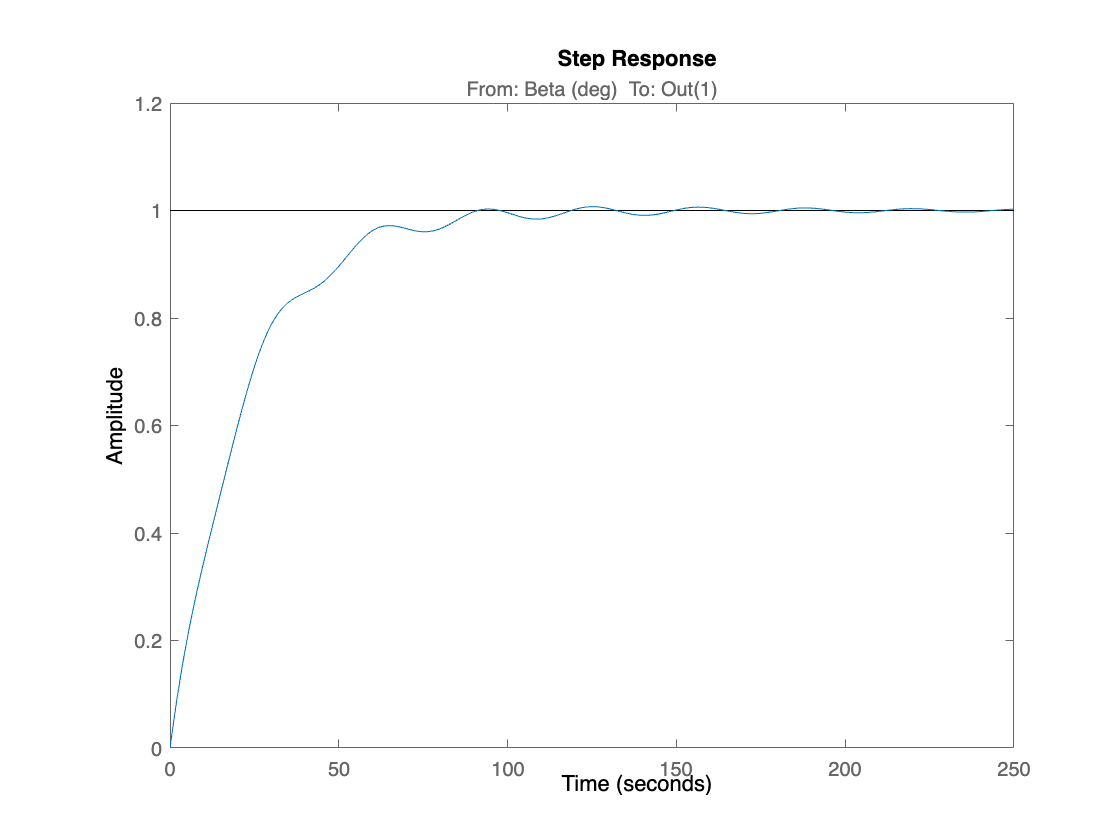


% Plot closed-loop step response of controlled system
figure('Name', 'Step response of SISO system with reference tracking PI controller');
step(T);

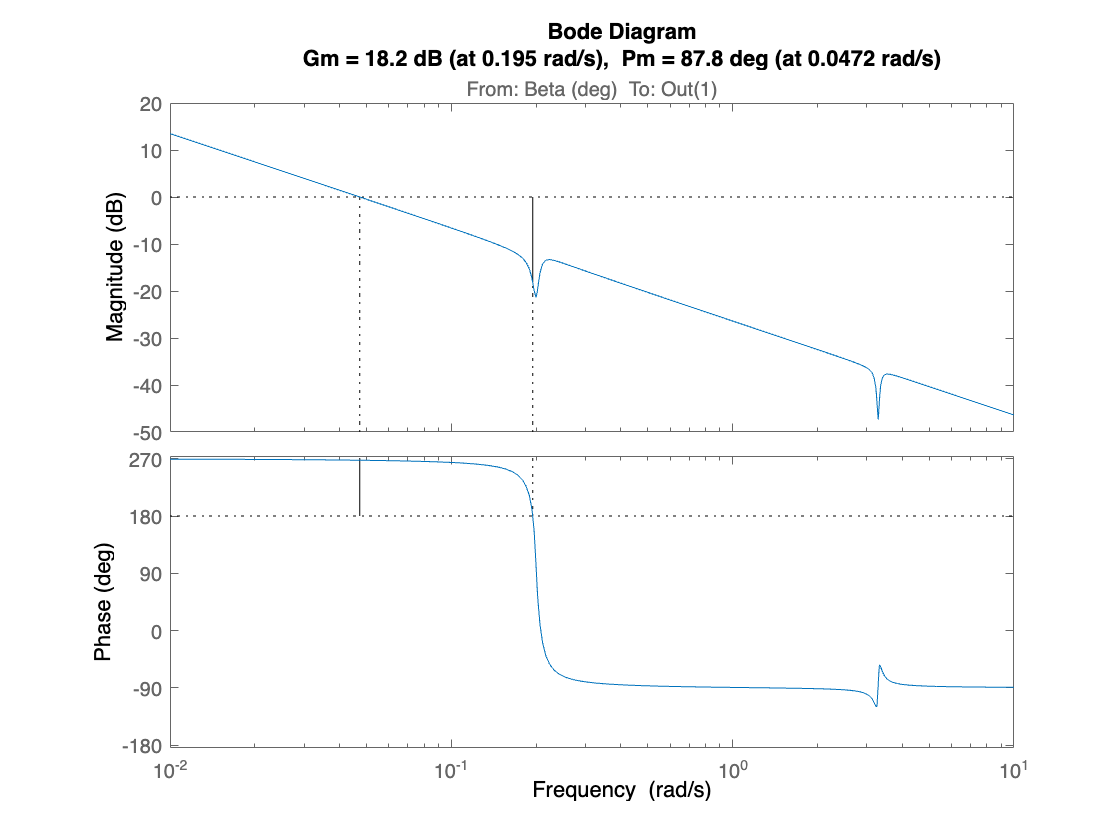


% Bode plot with margins of open-loop system
figure('Name', 'Bode plot of SISO system with reference tracking PI controller');
margin(L);

## output disturbance rejection

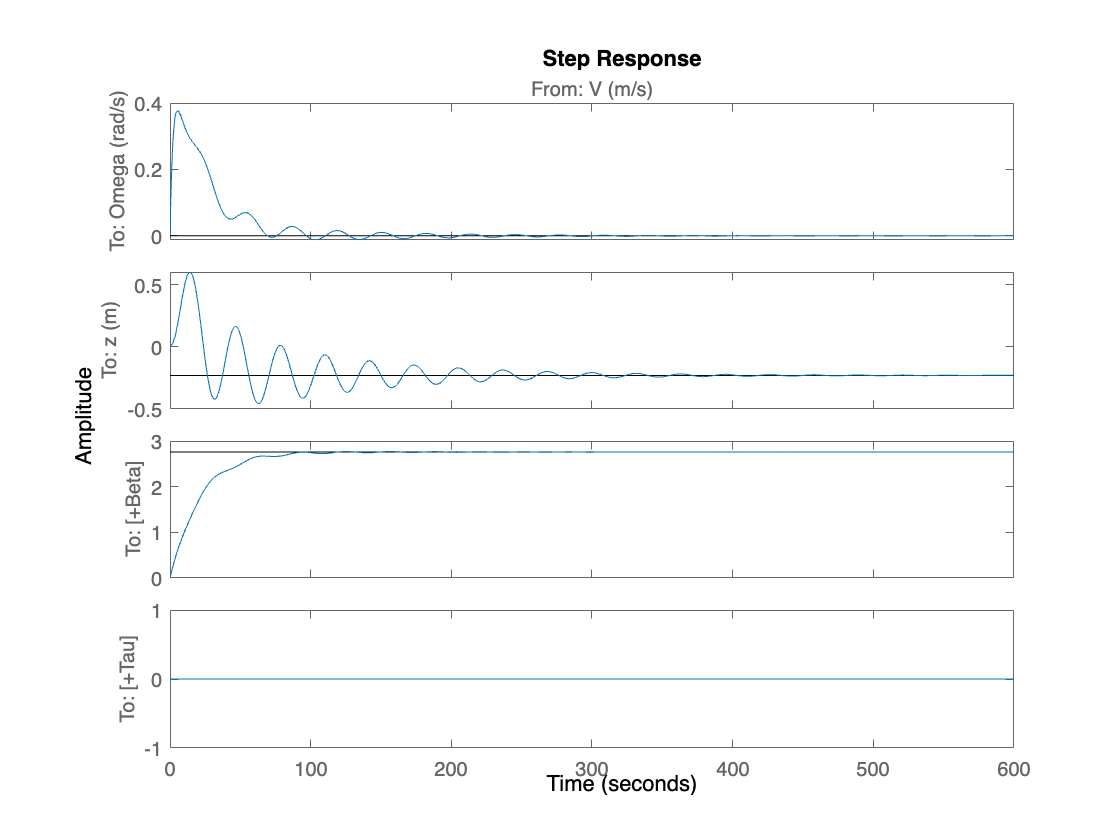


% Use the SISO controller designed for reference tracking for disturbance rejection
controller_dist = C_ref;

% Construct a generalized plant for simulation reasons
warning off
systemnames = 'FWT';   
inputvar = '[V; Beta; Tau]';    % Input generalized plant
input_to_FWT = '[Beta; Tau; V]';
outputvar = '[FWT; Beta; Tau; FWT]';    % Output generalized plant also includes the inputs
sysoutname = 'Gsim';
sysic;
warning on

% Construct SISO controller for disturbance rejection
CL_sisocontroller_dist = minreal(lft(Gsim(1:end-1,1:end-1), controller_dist));


% Plot step response of the SISO controller for disturbance rejection
figure('Name', 'Step response of SISO system controlled with reference tracking PI controller used for disturbance rejection')
step(CL_sisocontroller_dist);

## Multi Variable Mixed-Sensitivity

mimo_sys = FWT(1:2,1:2); %input beta&tau, output omega&z 
mimo_sys = minreal(mimo_sys);

% Construct RGA for omega = 0
G_0 = evalfr(mimo_sys,0);
S_0 = pinv(G_0)';
RGA_0 = G_0.*S_0;
disp('RGA for omega = 0');

RGA for omega = 0


disp(RGA_0);

   -0.6554    1.6554
    1.6554   -0.6554



%RGA for omega = 0.3*2*pi
G_0_3 = evalfr(mimo_sys,0.3*2*pi);
S_0_3 = pinv(G_0_3)';
RGA_0_3 = G_0_3.*S_0_3;
disp('RGA for omega = 0.3x2pi')

RGA for omega = 0.3x2pi


disp(RGA_0_3);

   -0.1166    1.1166
    1.1166   -0.1166



% 2.1 poles and zeros mimo

mimo_poles = pole(mimo_sys);
disp('MIMO poles:')

MIMO poles:


disp(mimo_poles);

  -0.0832 + 3.2936i
  -0.0832 - 3.2936i
  -0.4104 + 0.0000i
  -0.0106 + 0.2022i
  -0.0106 - 0.2022i




% Display zeros of the MIMO system
mimo_zeros = tzero(mimo_sys);
disp('MIMO zeros:')

MIMO zeros:


disp(mimo_zeros);

  -0.0078 + 1.2358i
  -0.0078 - 1.2358i



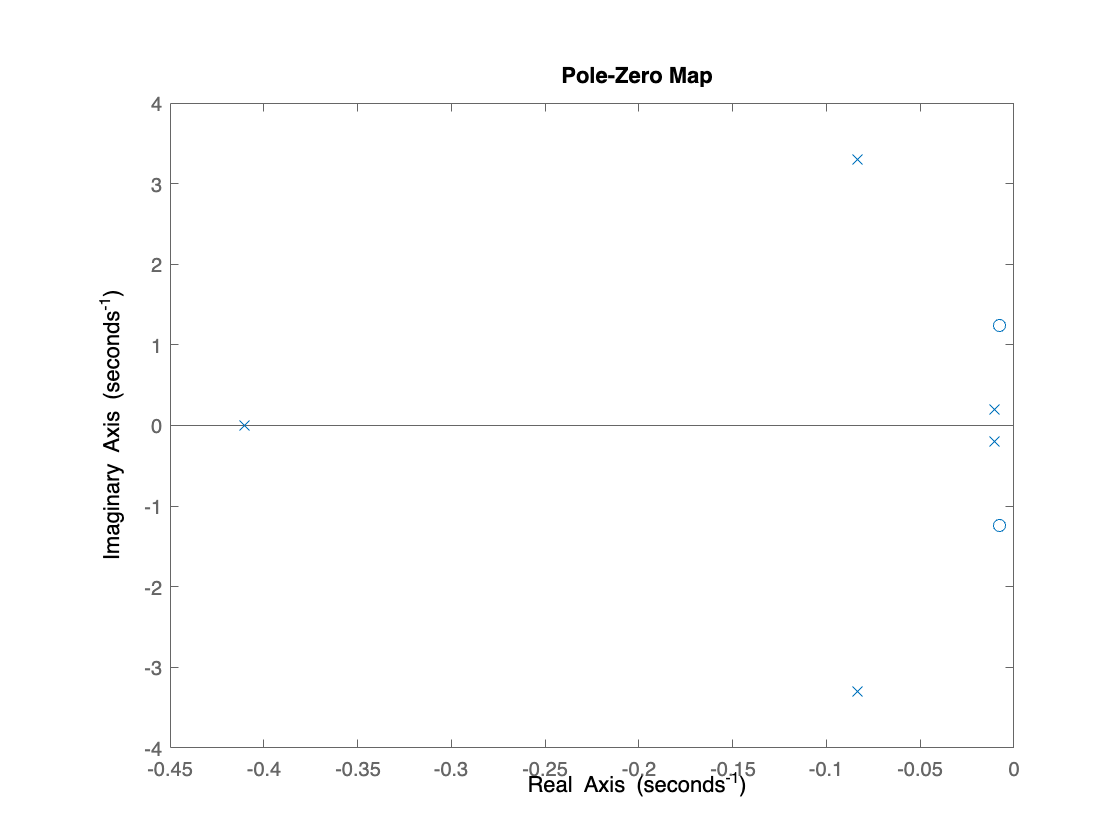


% Display Pole-zero map
figure('Name', 'Pole-zero map of MIMO system');
pzmap(mimo_sys);

% 2.3 design W_p11 

% Define parameters as defined in the problem discription
s = tf('s');
wB1 = 0.3 * 2 * pi;
a = 1 / 10000;
M = 3;



% Define Wp matrix
Wp=ss([((s/M)+wB1)/(s+wB1*a),0; 0 , 0.05]); 

%wp_11 = ((s/M) + wB1) / (s + wB1*a);
%disp(wp_11);


% Define Wu matrix
Wu=ss([0.005,0;0,(5*(10^(-3))*s^2+ 7*(10^(-4)*s)+5*(10^(-5)))/(s^2+14*(10^(-4))*s+(10^(-6)))]);

%2.5

% Construct G_mimo transfer function from state space of plant
G_mimo = tf(mimo_sys);

% Construct elements of generalized plant P
P11 = [Wp; zeros(2, 2)];
P12 = [Wp * G_mimo; Wu];
P21 = -eye(2);
P22 = -G_mimo;

% Construct minimal realization of generalized plant P
P = ss([P11, P12; P21, P22]);
P = minreal(P);

16 states removed.



% Find and display number of states in the plant
states_gen_plant = size(P.A, 1);
disp(['Number of states in plant: ' num2str(states_gen_plant)]);

Number of states in plant: 8
